close('all'); clear; clc;
setmadsympath();
sympref("FloatingPointOutput",false);

## Geometry

The Sharp model considers a left-handed frame (North, West, Down).

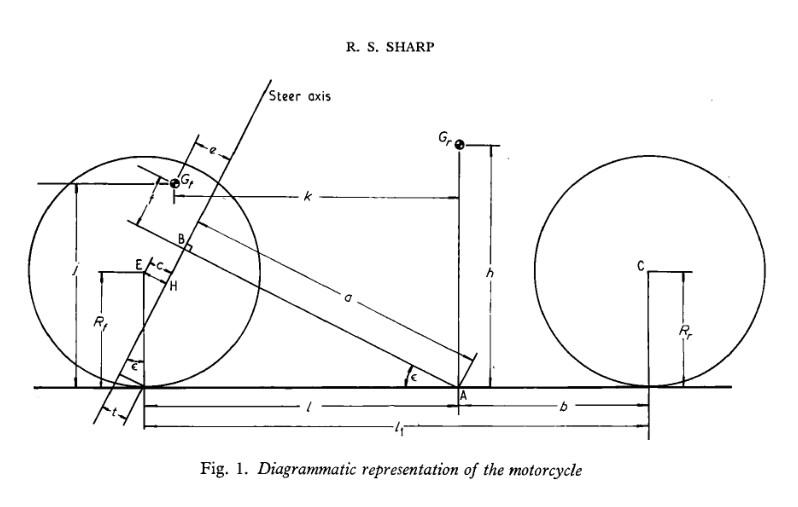

Create the caster frame:

caster = newParameters('varepsilon');
N = Frame;
Nc = N.orientNew('y',caster);

Solve for the front wheelbase $l$:

[a,an,l] = newParameters('a','a_n','l');
Pa = Point;
Pb = Pa.locateNew(a*Nc.x);
eqn = cos(caster) - a/(l + an/cos(caster));
l = solve(eqn,l);

Locate the front wheel center $E$:

rf = newParameters('r_f');
E = Pa.locateNew(l*N.x - rf*N.z);
rE = E.posFrom;
pprint(rE)

$$\left[\begin{array}{c} \frac{a-a_{n}}{c_{\varepsilon }}\\ 0\\ -r_{f} \end{array}\right]$$

Now locate the front wheel center relative to the intersection between the front chassis chord and the steering axis:

rBE = E.posFrom(Pb,Nc);
rBE = simplify(expand(rBE));

lx = rBE(1);
pprint(lx);

$$r_{f}\,s_{\varepsilon }-a_{n}$$


lz = rBE(3);
pprint(lz);

$$-\frac{r_{f}\,{c_{\varepsilon }}^{2}-a\,s_{\varepsilon }+a_{n}\,s_{\varepsilon }}{c_{\varepsilon }}$$

Now solve for the front chassis chord $a$ and the height $f$ of the front chassis mass center in the caster frame to obtain a simplifying substitution for $l_{z}$:

[e,f,j,k] = newParameters('e','f','j','k');

Gfa = Pa.locateNew(k*N.x - j*N.z);
Gf = Pb.locateNew(e*Nc.x + f*Nc.z);

sol_af = solve(Gf.posFrom(Gfa),[a,f]);
lz_sub = subs(lz,a,sol_af.a);
lz_sub = simplify(expand(lz_sub));
pprint(lz_sub)

$$-\frac{a_{n}\,s_{\varepsilon }-j+e\,s_{\varepsilon }+{c_{\varepsilon }}^{2}\,j+{c_{\varepsilon }}^{2}\,r_{f}-c_{\varepsilon }\,k\,s_{\varepsilon }}{c_{\varepsilon }}$$

## Kinematics

N = Frame;
O = Point;

### Sharp origin

Orientation : 

yaw = dynamicVariable("psi");
Nyaw = N.orientNew('z',yaw);

Position :

[px,py] = dynamicVariables('x','y');
Pa = O.locateNew(px.*N.x + py.*N.y);

### Rear chassis

Orientation:

lean = dynamicVariable("varphi");
Nlean = Nyaw.orientNew('x',lean);
pprint(Nlean.dcm)

$$\left[\begin{array}{ccc} c_{\psi } & -c_{\phi }\,s_{\psi } & s_{\psi }\,s_{\phi }\\ s_{\psi } & c_{\psi }\,c_{\phi } & -c_{\psi }\,s_{\phi }\\ 0 & s_{\phi } & c_{\phi } \end{array}\right]$$

Position:

h = newParameters('h');
Gr = Pa.locateNew(-h.*Nlean.z);
pprint(Gr.posFrom)

$$\left[\begin{array}{c} x-h\,s_{\psi }\,s_{\phi }\\ y+c_{\psi }\,h\,s_{\phi }\\ -c_{\phi }\,h \end{array}\right]$$

### Rear wheel

Orientation:

pitch_r = dynamicVariable("theta_r");
Npitch_r = Nlean.orientNew('y',pitch_r);
pprint(Npitch_r.dcm);

$$\left[\begin{array}{ccc} c_{\psi }\,c_{\theta ,r}-s_{\psi }\,s_{\theta ,r}\,s_{\phi } & -c_{\phi }\,s_{\psi } & c_{\psi }\,s_{\theta ,r}+c_{\theta ,r}\,s_{\psi }\,s_{\phi }\\ c_{\theta ,r}\,s_{\psi }+c_{\psi }\,s_{\theta ,r}\,s_{\phi } & c_{\psi }\,c_{\phi } & s_{\psi }\,s_{\theta ,r}-c_{\psi }\,c_{\theta ,r}\,s_{\phi }\\ -c_{\phi }\,s_{\theta ,r} & s_{\phi } & c_{\theta ,r}\,c_{\phi } \end{array}\right]$$

Position:

[b,rr] = newParameters('b','r_r');
Wr = Pa.locateNew(-b.*Nlean.x -rr.*Nlean.z);
pprint(Wr.posFrom)

$$\left[\begin{array}{c} x-b\,c_{\psi }-r_{r}\,s_{\psi }\,s_{\phi }\\ y-b\,s_{\psi }+c_{\psi }\,r_{r}\,s_{\phi }\\ -c_{\phi }\,r_{r} \end{array}\right]$$

### Rear contact point

Cr = Wr.locateNew(rr*Nlean.z);
rWrCr = Cr.posFrom(Wr,Npitch_r);
pprint(rWrCr)

$$\left[\begin{array}{c} -r_{r}\,s_{\theta ,r}\\ 0\\ c_{\theta ,r}\,r_{r} \end{array}\right]$$

### Front chassis

Orientation:

Ncaster = Nlean.orientNew('y',caster);
steer = dynamicVariable("delta");
Nsteer = Ncaster.orientNew('z',steer);
pprint(Nsteer.dcm())

$$\left[\begin{array}{ccc} c_{\delta }\,c_{\psi }\,c_{\varepsilon }-c_{\phi }\,s_{\delta }\,s_{\psi }-c_{\delta }\,s_{\psi }\,s_{\phi }\,s_{\varepsilon } & s_{\delta }\,s_{\psi }\,s_{\phi }\,s_{\varepsilon }-c_{\psi }\,c_{\varepsilon }\,s_{\delta }-c_{\delta }\,c_{\phi }\,s_{\psi } & c_{\psi }\,s_{\varepsilon }+c_{\varepsilon }\,s_{\psi }\,s_{\phi }\\ c_{\psi }\,c_{\phi }\,s_{\delta }+c_{\delta }\,c_{\varepsilon }\,s_{\psi }+c_{\delta }\,c_{\psi }\,s_{\phi }\,s_{\varepsilon } & c_{\delta }\,c_{\psi }\,c_{\phi }-c_{\varepsilon }\,s_{\delta }\,s_{\psi }-c_{\psi }\,s_{\delta }\,s_{\phi }\,s_{\varepsilon } & s_{\psi }\,s_{\varepsilon }-c_{\psi }\,c_{\varepsilon }\,s_{\phi }\\ s_{\delta }\,s_{\phi }-c_{\delta }\,c_{\phi }\,s_{\varepsilon } & c_{\delta }\,s_{\phi }+c_{\phi }\,s_{\delta }\,s_{\varepsilon } & c_{\phi }\,c_{\varepsilon } \end{array}\right]$$

Position:

Pb = Pa.locateNew(a.*Ncaster.x);
Gf = Pb.locateNew(e.*Nsteer.x + f.*Nsteer.z);

### Front wheel

Orientation:

yaw_f = dynamicVariable("psi_f");
Nyaw_f = N.orientNew('z',yaw_f);

lean_f = dynamicVariable("varphi_f");
Nlean_f = Nyaw_f.orientNew('x',lean_f);

pitch_f = dynamicVariable("theta_f");
Npitch_f = Nlean_f.orientNew('y',pitch_f);

pprint(Npitch_f.dcm)

$$\left[\begin{array}{ccc} c_{\psi ,f}\,c_{\theta ,f}-s_{\psi ,f}\,s_{\theta ,f}\,s_{\phi ,f} & -c_{\phi ,f}\,s_{\psi ,f} & c_{\psi ,f}\,s_{\theta ,f}+c_{\theta ,f}\,s_{\psi ,f}\,s_{\phi ,f}\\ c_{\theta ,f}\,s_{\psi ,f}+c_{\psi ,f}\,s_{\theta ,f}\,s_{\phi ,f} & c_{\psi ,f}\,c_{\phi ,f} & s_{\psi ,f}\,s_{\theta ,f}-c_{\psi ,f}\,c_{\theta ,f}\,s_{\phi ,f}\\ -c_{\phi ,f}\,s_{\theta ,f} & s_{\phi ,f} & c_{\theta ,f}\,c_{\phi ,f} \end{array}\right]$$

Position:

rBWf = lx.*Nsteer.x + lz.*Nsteer.z;
Wf = Pb.locateNew(rBWf);

### Front contact point

Cf = Wf.locateNew(rf.*Nlean_f.z);
rWfCf = Cf.posFrom(Wf,Npitch_f);
pprint(rWfCf)

$$\left[\begin{array}{c} -r_{f}\,s_{\theta ,f}\\ 0\\ c_{\theta ,f}\,r_{f} \end{array}\right]$$

## Rigid bodies

### Rear chassis

mr = newParameters('m_r');

names = {
    'I_rx';
    'I_ry';
    'I_rz'
    };

[Irx,Iry,Irz] = newParameters(names{:});
Crxz = newParameters("C_rxz");
Ir = inertia(Irx,Iry,Irz,'Ixz',Crxz);
Bb = Body(Nlean,Gr,Ir,mr);

### Rear wheel

iry = newParameters('i_ry');
Irw = inertia(0,iry,0);
Br = Body(Npitch_r,Wr,Irw,0);

### Front chassis

names = {
    'm_f';
    'I_fx';
    'I_fz'
    };

[mf,Ifx,Ifz] = newParameters(names{:});
If = inertia(Ifx,0,Ifz);
Bh = Body(Nsteer,Gf,If,mf);

### Front wheel

ify = newParameters('i_fy');
Ifw = inertia(0,ify,0);
Bf = Body(Npitch_f,Wf,Ifw,0);

## Generalized coordinates

qall = [
    yaw;
    lean;
    steer;
    px;
    py;
    pitch_r;
    yaw_f;
    lean_f;
    pitch_f
    ];

qdep = [
    pitch_r;
    yaw_f;
    lean_f;
    pitch_f
    ];

v = sym('v');
q0 = zeros(size(qall));
qd0 = [0,0,0,v,0,0,0,0,0];

q = GeneralizedCoordinates(qall,qdep,q0,qd0);

## Generalized speeds

names = {
    'omega_psi';
    'omega_varphi';
    'omega_theta_r';
    'omega_delta';
    'v_y'
    };

uind = dynamicVariables(names{:});
udep = dynamicVariables('u',6:9);

uall = [
    uind;
    udep
    ];

u0 = zeros(numel(uall),1);

u = GeneralizedCoordinates(uall,udep,u0);

## Auxiliary speeds

[Yr,Yf] = dynamicVariables("Y_r","Y_f");
Y0 = zeros(2,1);
Y = GeneralizedCoordinates([Yr;Yf],[],Y0);

## Holonomic constraints

spin_x = Nsteer.y(1) - Nlean_f.y(1);
spin_z = Nsteer.y(3) - Nlean_f.y(3);

hc = [
    spin_z;
    spin_x
    ];

hc = simplify(expand(hc));

pprint(hc)

$$\left[\begin{array}{c} c_{\delta }\,s_{\phi }-s_{\phi ,f}+c_{\phi }\,s_{\delta }\,s_{\varepsilon }\\ c_{\phi ,f}\,s_{\psi ,f}-c_{\delta }\,c_{\phi }\,s_{\psi }-c_{\psi }\,c_{\varepsilon }\,s_{\delta }+s_{\delta }\,s_{\psi }\,s_{\phi }\,s_{\varepsilon } \end{array}\right]$$

## Nonholonomic constraints

no_slip_r = noslip(Br,rWrCr,Nyaw);
no_slip_f = noslip(Bf,rWfCf,Nyaw_f);

nhc = [
    N.x.'*no_slip_r;
    N.x.'*no_slip_f
    ];

nhc = simplify(expand(nhc));
cons = ConstraintEquations(q,hc,nhc);

## Kinematic equations

Ta = Pose(Nyaw,Pa);
Va = Twist(Ta).vector();

kdes = [
    u.All(1:2) - Va(4:5);
    u.All(3:5) - diff(q.All(3:5))
    ];

## Tire equations

TCr = Pose(Nyaw,Cr);
TCf = Pose(Nyaw_f,Cf);

VCr = Twist(TCr).vector();
vCr = VCr(4:5);

VCf = Twist(TCf).vector();
vCf = VCf(4:5);

rl = newParameters('sigma');

names = {
    'C_r1';
    'C_r2';
    'C_f1';
    'C_f2'
    };

[Cr1,Cr2,Cf1,Cf2] = newParameters(names{:});

slip_r = atan(vCr(2)/vCr(1));
slip_f = atan(vCf(2)/vCf(1));

eqYr = vCr(1)*(Yr + Cr1*slip_r - Cr2*lean);
eqYf = vCf(1)*(Yf + Cf1*slip_f - Cf2*lean_f);
eqY = [
    rl*diff(Yr) + eqYr;
    rl*diff(Yf) + eqYf
    ];

## Forces and moments

### Rear tire

% Zr = newParameters('Z_r');
% Br.applyForce(Nyaw,Cr,Yr*N.y + Zr.*N.z);

### Front tire

% Zf = newParameters('Z_f');
% Bf.applyForce(Nyaw_f,Cf,Yf.*N.y + Zf.*N.z);

### Steering torque

% Csteer = newParameters('C_delta');
% Mz = (Msteer - Csteer*u.All(5)).*N.z;
% Bh.applyMoment(Nsteer,Mz);
% Bb.applyMoment(Nsteer,-Mz);

### Gravity

% bodies = [
%     Bb;
%     Br;
%     Bh;
%     Bf
%     ];
% 
% g = newParameters('g');
% fp = @(b)b.MassCenter;
% fFg = @(b)(b.Mass*g).*N.z;
% fg = @(b)b.applyForce(N,fp(b),fFg(b));
% arrayfun(fg,bodies);